ps_path = 'ps_data';
fileStruct =dir(fullfile(ps_path, '*.csv'));

numFiles = length(fileStruct);
allData = cell(1, numFiles);



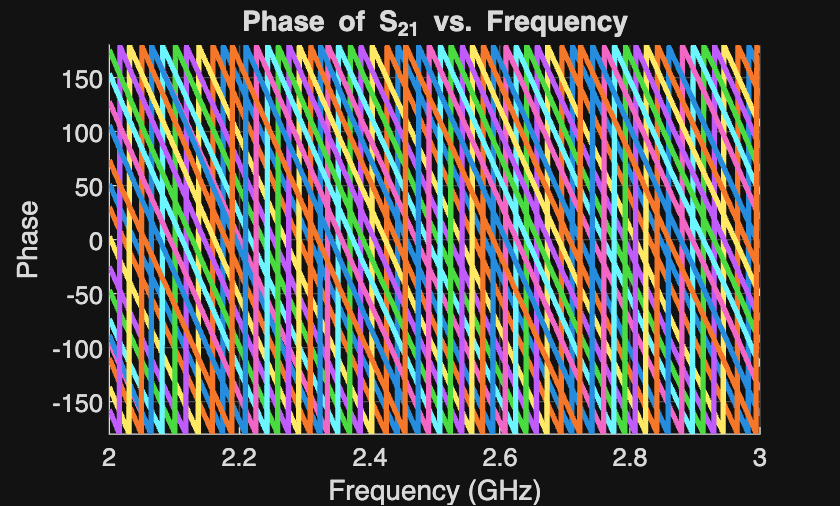

    figure; 
    hold on;
    gifFile = 'PSPlot.gif';
for i = 1:numFiles
    filePath = fullfile(ps_path, fileStruct(i).name);
    data = readmatrix(filePath);
    allData{i} = data;
    % Column 1: Frequency in Hz
    % Column 2: Real part of S21
    % Column 3: Imaginary part of S21
    Freq_Hz = data(:, 1);
    Re_S21 = data(:, 2);
    Im_S21 = data(:, 3);
    
    
    S21_complex = Re_S21 + 1j * Im_S21;
    
    
    Phase_rad = angle(S21_complex);
    
    Phase_deg = rad2deg(Phase_rad);
    
    

    plot(Freq_Hz / 1e9, Phase_deg, 'LineWidth', 2); 
    
    title('Phase of S_{21} vs. Frequency');
    xlabel('Frequency (GHz)');
    ylabel('Phase'); 
    grid on;
    drawnow;
    ylim([-180, 180]);
    exportgraphics(gcf, gifFile, 'Append', true);
        
end

fprintf('done!');

done!